# El Modelo de población

El modelo logístico de población se describe mediante una ecuación diferencial que captura el crecimiento poblacional en un entorno con recursos limitados. Este enfoque considera la **capacidad de carga** del entorno, es decir, el número máximo de individuos que el medio puede sostener de manera sostenible. A diferencia de modelos que asumen un crecimiento ilimitado, el modelo logístico integra explícitamente las restricciones impuestas por la disponibilidad finita de recursos, estableciendo un límite superior para la población alcanzable. De este modo, refleja de manera más realista la dinámica poblacional en ecosistemas finitos.

La formulación básica es la siguiente:


$$\dot{N} =\textrm{rN}\left(1-\frac{N}{K}\right)$$


- $\dot{N}$es la tasa de cambio de la población con respecto al tiempo.

- $N$es el tamaño de la población al instante $t$.

- $r$ es la tasa intrísica de crecimiento de la población

- $K$es la capacidad de carga del entorno, es decir, el número máximo de individuos que el entorno puede mantener.

Esta ecuación se puede resolver analíticamente, sin embargo, vamos a analizarla usando el enfoque geométrico que ofrece el espacio de fase $\left(\dot{N} ,N\right)$.

Los puntos fijos ocurren en $N^* =0$ y $N^* =K$.

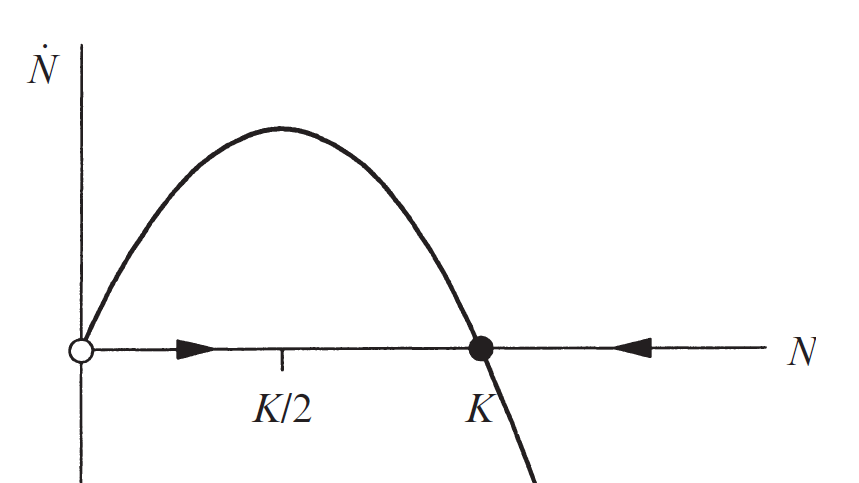

**Figura 1:** Espacio de fase $\left(\dot{N} ,N\right)$para $N>0$.

Analizando el flujo de la Figura3, vemos que $N^* =0$ es inestable, y $N^* =K$ es estable. 

Tambien, podemos obtener información sobre el aspecto de la solución. En efecto, si $N_0 <\frac{K}{2}$, la población crece rápidamente hasta alcanzar $N=\frac{K}{2}$ . A partir de ese punto, la población crece a un ritmo suave hasta alcanza la capcidad máxima.

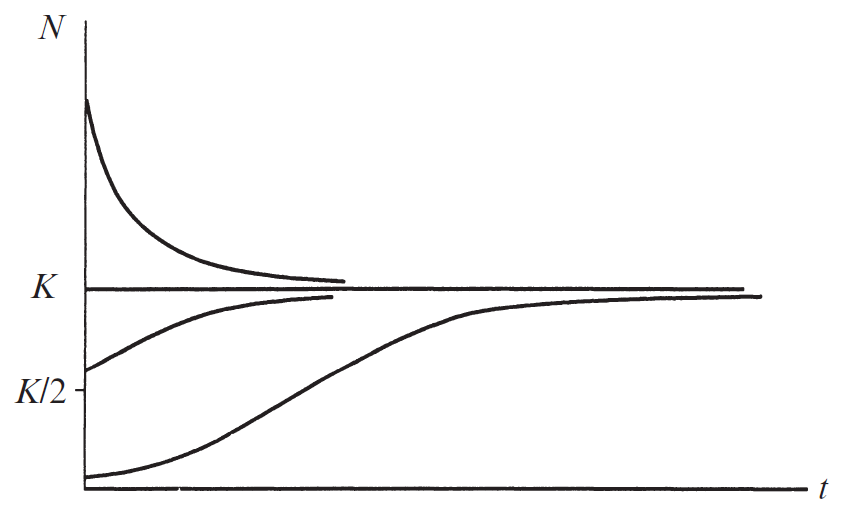

**Figura 2:** Evolución de la población en el tiempo.


% Limpia el espacio de trabajo
clear all; close all; clc;

% Define las variables simbólicas
syms N r K

% Define la ecuación diferencial
ode_rhs = r * N * (1 - N/K); % dN/dt

% Encuentra los puntos de equilibrio resolviendo dN/dt = 0
fixed_points = solve(ode_rhs == 0, N,'ReturnConditions',true);
disp('Puntos de equilibrio:');

Puntos de equilibrio:


disp(fixed_points.N);

$$\left(\begin{array}{c} 0\\ K \end{array}\right)$$


% Calcula la derivada de la ecuación diferencial para evaluar la estabilidad
ode_rhs_deriv = diff(ode_rhs, N);
stabilities_0 = subs(ode_rhs_deriv, N, fixed_points.N(1))

$$stabilities\_0 = r$$

stabilities_K = subs(ode_rhs_deriv, N, fixed_points.N(2))

$$stabilities\_K = -r$$

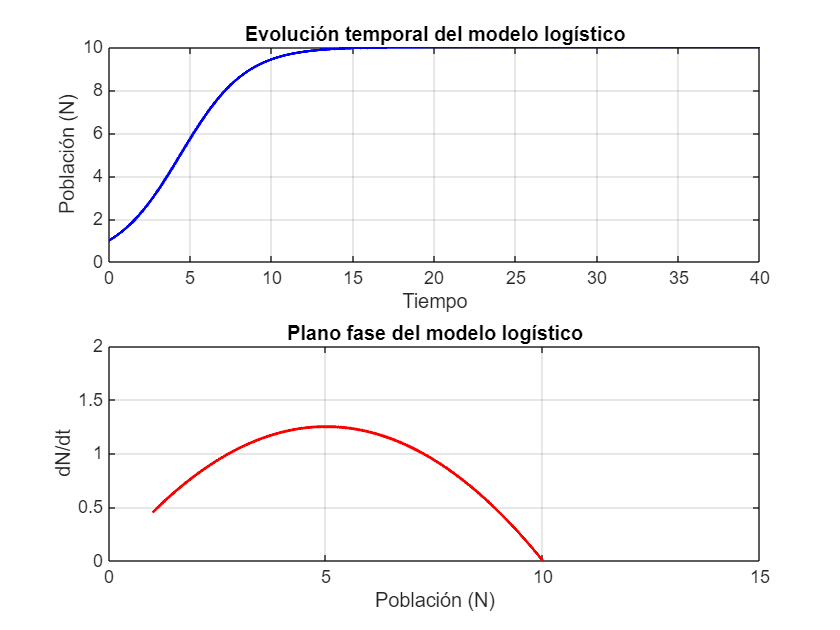

Simulación completa.



% --- Simulación numérica ---
% Define los parámetros del modelo
r = 0.5;  % Tasa de crecimiento
K = 10;   % Capacidad de carga

% Define el sistema como una función anónima para ode45
logistic_model = @(t, N) r * N * (1 - N/K);

% Define las condiciones iniciales
N0 = 1; % Población inicial

% Define el intervalo de tiempo
tspan = 0:.01:40; % Simulación de 0 a 50 unidades de tiempo

% Simula la dinámica del sistema utilizando ode45
[t, N] = ode45(logistic_model, tspan, N0);

% --- Visualización de resultados ---
figure;
% Evolución temporal de la población
subplot(2, 1, 1);
plot(t, N, 'b', 'LineWidth', 1.5);
xlabel('Tiempo');
ylabel('Población (N)');
title('Evolución temporal del modelo logístico');
grid on;

% Plano fase
subplot(2, 1, 2);
plot(N, r * N .* (1 - N/K), 'r', 'LineWidth', 1.5);
xlabel('Población (N)');
ylabel('dN/dt');
title('Plano fase del modelo logístico');
grid on;
axis([0 15 0 2])

# Ejemplo 2

#### Puntos estacionarios:

Este sistema de segundo orden puede reescribirse como un sistema de dos ecuaciones de primer orden:


$$\begin{array}{l}
x_1 =x\\
x_2 =\dot{\;x\;} 
\end{array}$$


Ahora dreviamos las variables $x_1 \;y\;x_2$:


$$\begin{array}{l}
\dot{\;x{\;}_1 } =x_2 \\
\dot{\;x_2 } =-{\mathrm{ax}}_2 \left({x_1 }^2 +{x_2 }^2 -1\right)-x_1 
\end{array}$$


# Estabilidad del sistema

% Limpia el espacio de trabajo y define variables simbólicas
clear all; close all; clc;
syms x y

a = 1;

% Define las ecuaciones del sistema
dx_dt = y; % Primera ecuación
dy_dt = -y*(x^2 + y^2 - 1) - x; % Segunda ecuación

% Encuentra los puntos de equilibrio resolviendo dx/dt = 0 y dy/dt = 0
[eq_x, eq_y] = solve([dx_dt == 0, dy_dt == 0], [x, y]);
equilibrium_points = [eq_x, eq_y];

% Muestra los puntos de equilibrio
disp('Puntos de equilibrio:');

Puntos de equilibrio:


disp(equilibrium_points);

$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$


% Calcula la matriz Jacobiana del sistema
jacobian_matrix = jacobian([dx_dt, dy_dt], [x, y]);

disp('Matriz Jacobiana:');

Matriz Jacobiana:


disp(jacobian_matrix);

$$\left(\begin{array}{cc} 0 & 1\\ -2\,x\,y-1 & -x^{2}-3\,y^{2}+1 \end{array}\right)$$


% Evalúa la matriz Jacobiana en cada punto de equilibrio
disp('Análisis de estabilidad en los puntos de equilibrio:');

Análisis de estabilidad en los puntos de equilibrio:


for i = 1:length(eq_x)
    % Sustituye el punto de equilibrio en la matriz Jacobiana
    J_eval = subs(jacobian_matrix, [x, y], [eq_x(i), eq_y(i)]);
    
    % Calcula los autovalores de la matriz Jacobiana
    eigenvalues = eig(J_eval);
    
    % Muestra los resultados
    fprintf('Punto de equilibrio (%s, %s):\n', char(eq_x(i)), char(eq_y(i)));
    disp('Autovalores:');
    disp(eigenvalues);
    
    % Determina la estabilidad
    if all(real(eigenvalues) < 0)
        fprintf('  Estable (atractor)\n');
    elseif any(real(eigenvalues) > 0)
        fprintf('  Inestable (repulsor)\n');
    else
        fprintf('  Marginalmente estable o caso indeterminado\n');
    end
end

Punto de equilibrio (0, 0):


Autovalores:


$$\left(\begin{array}{c} \frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ \frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

  Inestable (repulsor)


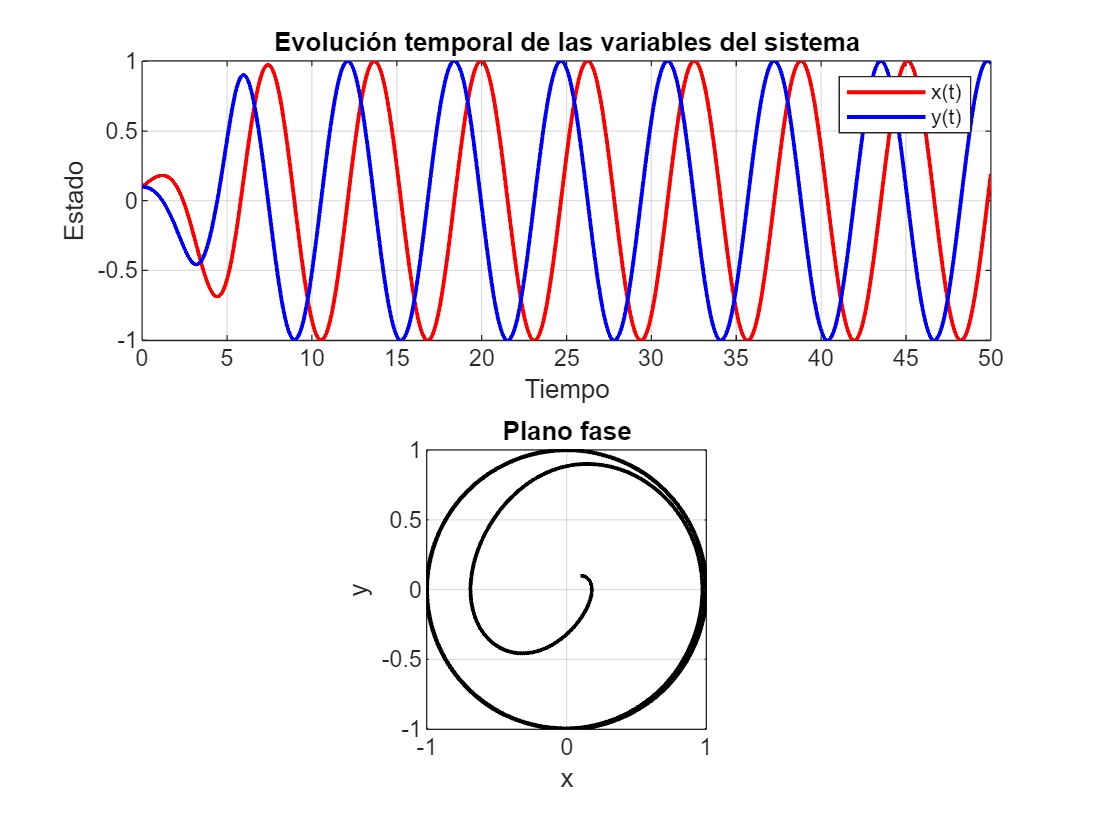

ode_system = @(t, state) [state(2); -state(2)*(state(1)^2 + state(2)^2 - 1) - state(1) ];

% Define las condiciones iniciales
x0 = 0.1; % Condición inicial para x
y0 = 0.1; % Condición inicial para y
initial_conditions = [x0, y0];

% Define el intervalo de tiempo para la simulación
tspan = 0:.01:50; % Simulación desde t=0 hasta t=20

% Realiza la simulación utilizando ode45
[t, sol] = ode45(ode_system, tspan, initial_conditions);

% Extrae las soluciones
x = sol(:, 1); % Componente x
y = sol(:, 2); % Componente y

% Grafica los resultados
figure;
subplot(2, 1, 1);
plot(t, x, 'r', 'LineWidth', 1.5); hold on;
plot(t, y, 'b', 'LineWidth', 1.5);
xlabel('Tiempo');
ylabel('Estado');
legend('x(t)', 'y(t)');
title('Evolución temporal de las variables del sistema');
grid on;

subplot(2, 1, 2);
plot(x, y, 'k', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
title('Plano fase');
grid on;axis square